# **Lab 1 - Q1 (Introductory Lab)**

### **Question 1**

*Consider the signal *$x\left(t\right)=\cos \left(2\pi \textrm{ft}\right)$*where *$f=2000\;\textrm{Hz}$

#### *Part 1(a)*

The minimum sampling frequency must meet the Nyquist sampling frequency which states that the *sampling frequency of a signal must be greater than or equal to twice the maximum frequency component of the signal*. That is:


$$f_{min} = F_s = 2 f_{max}$$


#### *Part 1(b)*

Suppose we want to plot 5 periods of the 'continuous' signal with a very fine sampling time of ${10}^{-6}$ seconds. The plotting code is shown below:

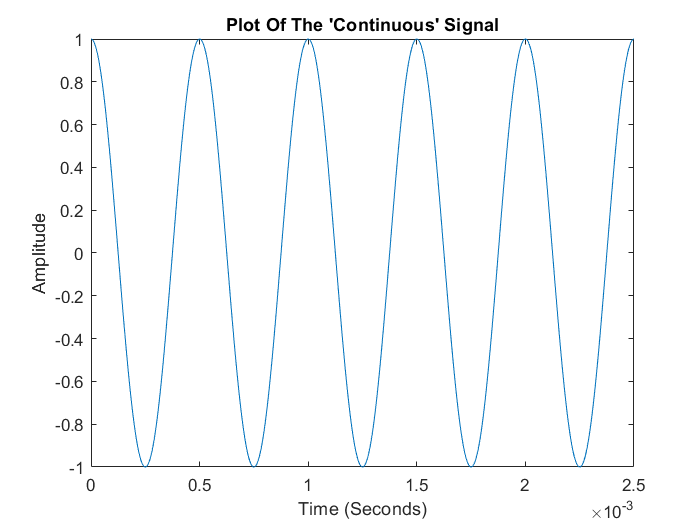

% Variable for sampling time (Ts_cont) and hence the sampling frequency (f_cont):
Ts_cont = 10^-6;
f_cont = 1/Ts_cont;

% Declare the frequency of the signal itself (f). A period of the signal is
% the inverse of its frequency:
f = 2000;
T = 1/f;

% Generate the time-axis to produce 5 periods in steps of the sampling
% period, Ts:
t = 0 : Ts_cont : 5*T;

% Generate the corresponding signal:
x = cos(2*pi*f*t);

% Create a figure and plot the 'continuous signal':
figure(1)
plot(t,x)
title("Plot Of The 'Continuous' Signal")
xlabel("Time (Seconds)")
ylabel("Amplitude")

#### *Part 1(c)*

Let the sampling frequency now be 1.5 times the initial sampling frequency we initialised ($f_{\min }$). That is:


$$f_s =1\ldotp 5f_{\min }$$


We want to plot this newly sampled signal on top of the 'continuous signal' plotted earlier. The code for this is shown below. Again, we wish to plot 5 periods of this signal:

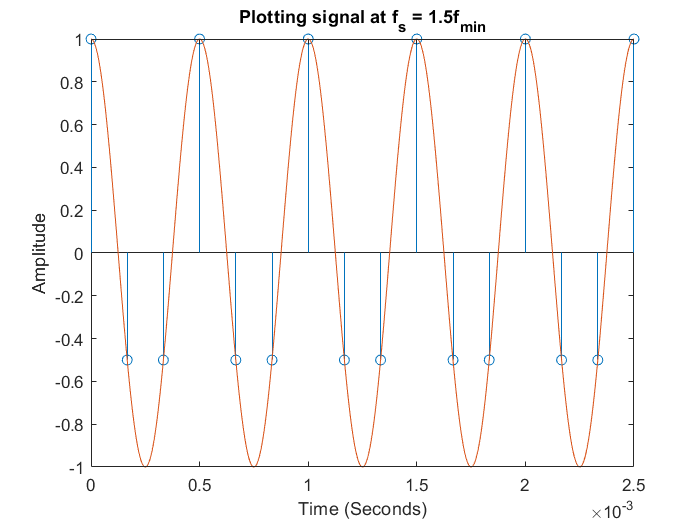

% Initialise the new sampling rate. We first compute what f_min is based on
% the Nyquist sampling theorem. This must be twice 2000 Hz.
f_min = 2*f;
T_min = 1/f_min;

% Now we increase the rate 1.5 times:
fs_c = 1.5 * f_min;

% Now we generate the corresponding time-axis for this new sampling rate.
t_c = 0 : 1/fs_c : 5*T;

% Generate the corresponding signal:
x_c = cos(2*pi*f*t_c);

figure(2)
stem(t_c,x_c)
hold on
plot(t,x)
title("Plotting signal at f_s = 1.5f_{min}")
xlabel("Time (Seconds)")
ylabel("Amplitude")

From the plot, we can see that in one period of the newly sampled signal, we have a 3 samples. The relationship between the the number of samples, the sampling frequency and the signals fundamental frequency is given by:


$$N=\frac{f_s }{f}$$


Using our parameter values we can see that if we rearrange for the signals' frequency, we have:


$$f=\frac{f_s }{N}=\frac{1\ldotp 5\times f_{\min } }{N}=\frac{1\ldotp 5\times \;4000\;\frac{\textrm{samples}}{s}}{3\;\textrm{samples}}=2000\;\textrm{Hz}$$


#### Part 1(d)

Now suppose we have sample at three-quarters of the minimum sampling rate. That is $f_s =0\ldotp 75f_{\min }$. 

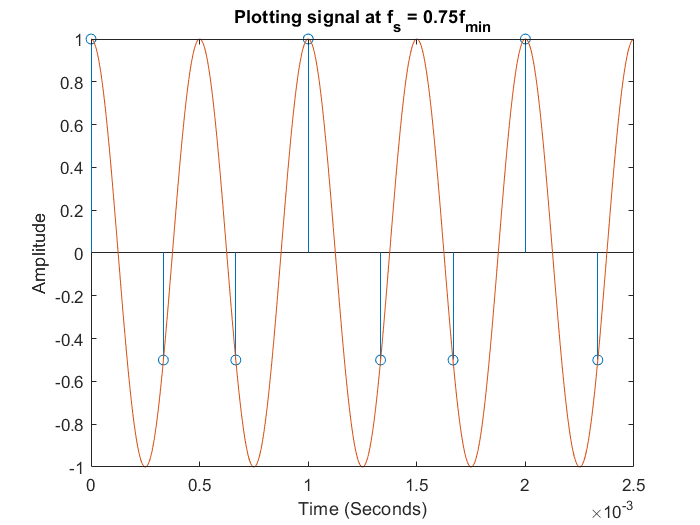

% Initialise the new sampling rate. We first compute what f_min is based on
% the Nyquist sampling theorem. This must be twice 2000 Hz.
f_min = 2*f;
T_min = 1/f_min;

% Now we increase the rate 0.75 times:
fs_d = 0.75 * f_min;

% Now we generate the corresponding time-axis for this new sampling rate.
t_d = 0 : 1/fs_d : 5*T;

% Generate the corresponding signal:
x_d = cos(2*pi*f*t_d);

figure(3)
stem(t_d,x_d)
hold on
plot(t,x)
title("Plotting signal at f_s = 0.75f_{min}")
xlabel("Time (Seconds)")
ylabel("Amplitude")

In this case, we can see that in a single period, we have 2 samples instead of three. The minimum frequency required for the signal to fit these two samples in one period is:


$$f=\frac{f_s }{N}=\frac{0\ldotp 75\times f_{\min } }{N}=\frac{0\ldotp 75\times 4000}{3}=1000\;\textrm{Hz}$$


### Part 1(e)

We now want to compute the DFT of the continuous signal and see how that compares to the spectra produced from the signals sampled at $1\ldotp 5f_{\min }$ and $0\ldotp 75f_{\min }$. A custom DFT function was made as my_dft.m. The DFT is computed for the 'continuous' signal below:

% Compute the FFT using 'my_dft':
X = my_dft(x_c, 1001)

f = 	1.0e+04 *

   -1.2000   -1.1976   -1.1952   -1.1928   -1.1904   -1.1880   -1.1856   -1.1832   -1.1808   -1.1784   -1.1760   -1.1736   -1.1712   -1.1688   -1.1664   -1.1640   -1.1616   -1.1592   -1.1568   -1.1544   -1.1520   -1.1496   -1.1472   -1.1448   -1.1424   -1.1400   -1.1376   -1.1352   -1.1328   -1.1304   -1.1280   -1.1256   -1.1232   -1.1208   -1.1184   -1.1160   -1.1136   -1.1112   -1.1088   -1.1064   -1.1040   -1.1016   -1.0992   -1.0968   -1.0944   -1.0920   -1.0896   -1.0872   -1.0848   -1.0824


X =    1.0000 + 0.0000i
   1.0134 + 0.2016i
   1.0607 + 0.4393i
   1.1748 + 0.7850i
   1.5000 + 1.5000i
   3.9465 + 5.9063i
  -1.0607 - 2.5607i
  -0.1347 - 0.6771i
  -0.0000 - 0.0000i
  -0.1347 + 0.6771i


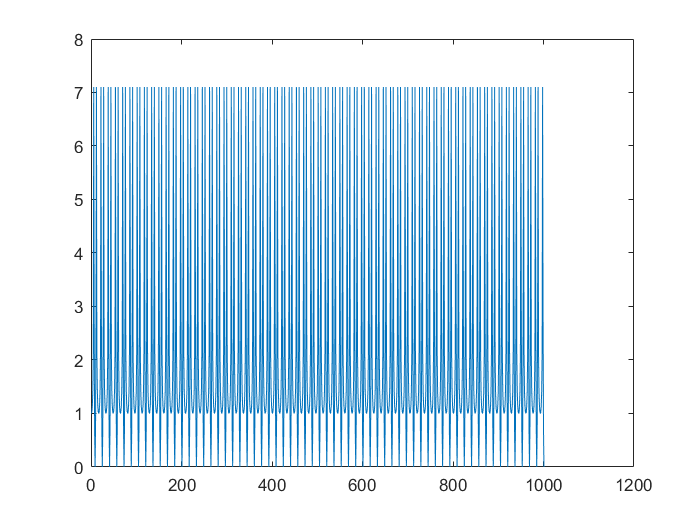


% At this point, the x-axis only represents the sample number on the
% frequency spectrum. We need this to reflect the true frequency axis.

% TO DO: Implement the 'fftshift' thing manually.mh

% plot both at the same time to compare:
figure(4)
plot(abs(X))